# Operaciones arreglo (elemento a elemento)

MATLAB tiene dos tipos diferentes de operaciones aritméticas: *operaciones arreglo* y *operaciones matriciales*. Es posible utilizar estas operaciones aritméticas para realizar cálculos numéricos. Por ejemplo, sumar dos números, elevar los elementos de una matriz a una potencia determinada o multiplicar dos matrices.

Las *operaciones arreglo* realizan las operaciones entre los **correspondientes elementos** de las matrices involucradas. No obstante, se debe destacar lo siguiente:

- Si las matrices tienen el **mismo tamaño**, entonces cada elemento de la primera matriz se empareja con el elemento en la misma ubicación de la segunda matriz.

- Si las matrices tienen **tamaños compatibles**, entonces cada entrada se expande implícitamente según sea necesario para que coincida con el tamaño de la otra.

- Si las matrices no son del mismo tamaño ni tienen tamaños compatibles, entonces no se realiza la operación y MATLAB devuelve un error.

Estas son algunas combinaciones de escalares, vectores y matrices que tienen tamaños compatibles:

**Figura 1.** Operación arreglo entre dos matrices que tienen el mismo tamaño.

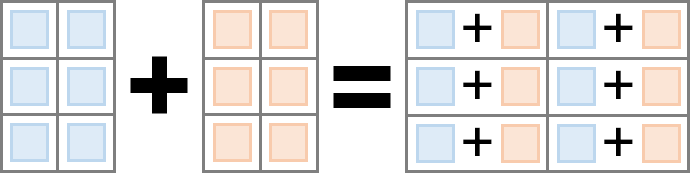

**Figura 2.** Operación arreglo entre una matriz y un escalar.

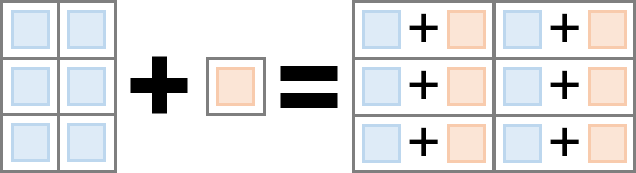

**Figura 3.** Operación arreglo entre una matriz y un vector fila. Ambos tienen el mismo número de columnas.

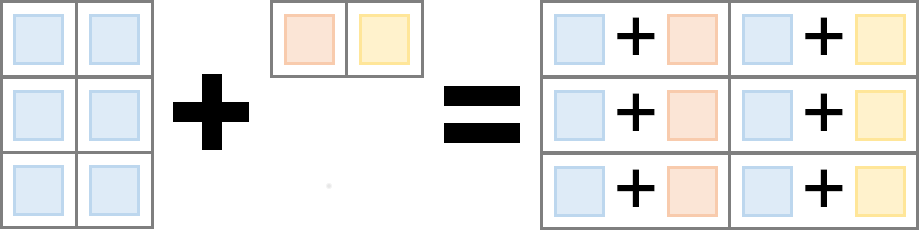

**Figura 4.** Operación arreglo entre un vector columna y un vector fila.

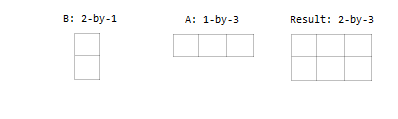

*Todas las imágenes fueron tomadas de la documentación oficial de MATLAB.*

Para obtener más información puede consultar el material adjunto en el material adicional.

v_row=1:10

v_row =      1     2     3     4     5     6     7     8     9    10


v_col=(1:10)'

v_col =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


v_row.*v_col

ans =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


## Operaciones elementales

Previamente se estudió las operaciones con escalares. Ahora se expandirá lo explicado anteriormente a operaciones elementales con matrices.

**Figura 5.** Todas las operaciones arreglo dentro de MATLAB.

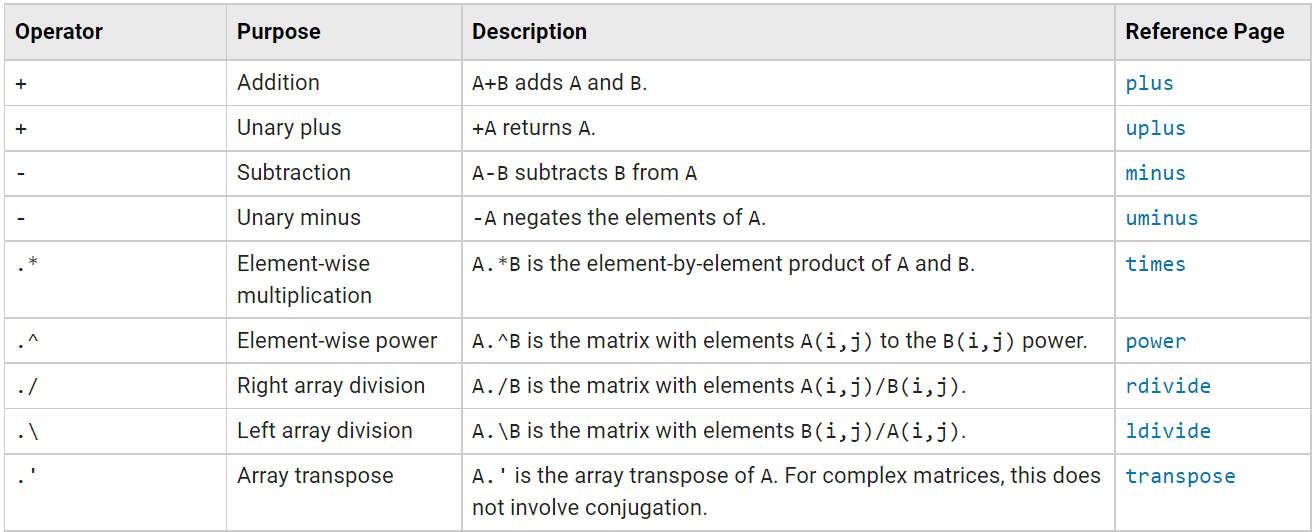

*Tomado de la documentación oficial de MATLAB.*

A=[1 2 3; 4 5 6i]

A =    1.0000 + 0.0000i   2.0000 + 0.0000i   3.0000 + 0.0000i
   4.0000 + 0.0000i   5.0000 + 0.0000i   0.0000 + 6.0000i


B=[1 2 3]

B =      1     2     3


A.*B

ans =    1.0000 + 0.0000i   4.0000 + 0.0000i   9.0000 + 0.0000i
   4.0000 + 0.0000i  10.0000 + 0.0000i   0.0000 +18.0000i


A./B

ans =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   4.0000 + 0.0000i   2.5000 + 0.0000i   0.0000 + 2.0000i


A.\B

ans =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.2500 + 0.0000i   0.4000 + 0.0000i   0.0000 - 0.5000i


Para todas las operaciones siempre se debe tener en cuenta el tamaño de las matrices involucradas, además de la expansión que se realizará siempre que sea posible.

### Ejercicio

Considerando la siguiente serie de Taylor


$$\ln \left(1-x\right)=-x-\frac{x^2 }{2}-\frac{x^3 }{3}-\cdots =-\sum_{n=1}^{\infty } \frac{x^n }{n}$$


Evaluar la serie de Taylor para $x=0\ldotp 5$ con 4 términos de expansión de la serie.

**Nota:** No utilizar bucles dado que todavía no se los ha estudiado.

### Solución

clear
clc
%datos
x=.5;
nmax=4;

%Generrar vector linealmente espaciado
n=1:nmax;

%%generar taylor
terminos=(x.^n)./n

terminos =     0.5000    0.1250    0.0417    0.0156


valorfinal=-sum(terminos)

valorfinal = -0.6823

realval=log(1-x)

realval = -0.6931

## Material adicional

- [Operaciones arreglo vs. Operaciones matriciales](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)

- [Tamaños de matriz compatibles para operaciones básicas](https://www.mathworks.com/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html)